% 换卫星改I正负号，帧头索引（根据子码相位确定），I的取点
% 把输出拉到最下面看CRC过没过，看frame1的前6个比特是否为PRN

## 提取导航电文

I = trackResults.I_Q(301:10:39980,1); % 每隔10个点取一个，电文比特10ms一个，从图上看从哪点取到哪点
I = double(I>0); % 转换成01比特

index = 1800-1295+2; % 帧头索引，判断导频分量子码相位获得
data = I(index:index+1800*1-1)'; % 连取若干帧，转成行向量，方便往Word里粘

## 解交织

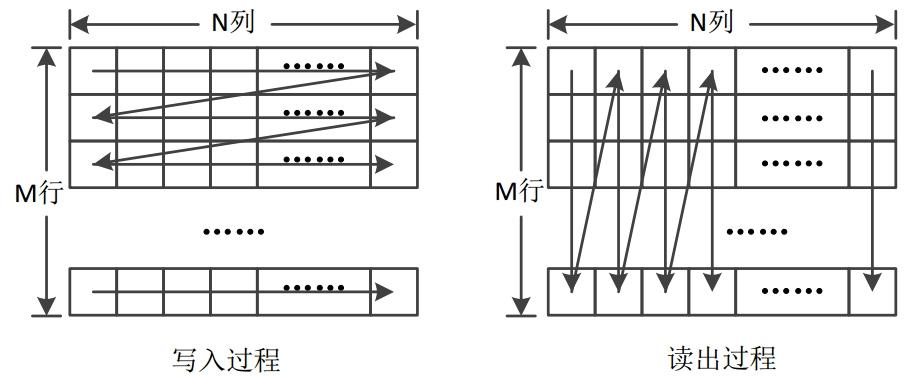


$$M=36,\;\;\;N=48$$


% 子帧2，1200比特，25行
% 子帧3，528比特，11行
% 两行子帧2，一行子帧3，最后三行为子帧2

frame1 = data(1:1800); % 第一帧，行向量
subFrameRaw23 = frame1(73:1800); % 解交织前2、3子帧，行向量
table = reshape(subFrameRaw23',36,48); % 排成表格

subFrame2_table = table([1,2,4,5,7,8,10,11,13,14,16,17,19,20,22,23,25,26,28,29,31,32,34,35,36],:); % 从表格中提取子帧2的行
subFrame2 = reshape(subFrame2_table',1,1200); % 排成一行，解交织后的子帧2

subFrame3_table = table([3,6,9,12,15,18,21,24,27,30,33],:); % 从表格中提取子帧3的行
subFrame3 = reshape(subFrame3_table',1,528); % 排成一行，解交织后的子帧3

## CRC校验

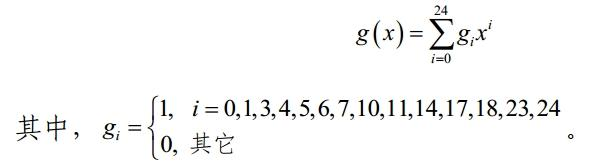

% CRC校验器
det = crc.detector([1 1 0 0 0 0 1 1 0 0 1 0 0 1 1 0 0 1 1 1 1 1 0 1 1]); % 降幂
% 子帧2
[~, error2] = detect(det, subFrame2(1:600)'); %输入数据列向量
if error2~=0 %为0表示正确
    disp('subframe2 error!')
end
% 子帧3
[~, error3] = detect(det, subFrame3(1:264)');
if error3~=0
    disp('subframe3 error!')
end
% 如果前面相位反了校验会错误